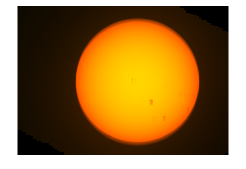

% Define directories
data_dir = 'C:\Users\jamie\Desktop\SharpCap Captures\2024-08-27\Capture\16_08_57';
save_dir = 'C:\Users\jamie\Pictures\astrophotos\processed';

% List all files in the data directory
data_files = dir(data_dir);
valid_extensions = {'.png', '.tif'};

% Initialize cell array to store images
images = {};

% Loop through each file and load if it has a valid extension
for k = 1:length(data_files)
    [~, ~, ext] = fileparts(data_files(k).name);
    if ismember(lower(ext), valid_extensions)
        data_path = fullfile(data_dir, data_files(k).name);
        
        % Read and convert the image to RGB format
        img = imread(data_path);
        if size(img, 3) == 1
            img = repmat(img, 1, 1, 3);  % Convert grayscale to RGB if necessary
        end
        
        images{end+1} = img;  % Append to cell array
    end
end

% Convert cell array to 4D array
images = cat(4, images{:});

% Get dimensions
[height, len, num_channels, num_images] = size(images);

% Calculate peak positions
peaks = zeros(num_images, 2);
for i = 1:num_images
    [~, ind] = max(images(:,:,1,i), [], 'all');
    [y, x] = ind2sub([height, len], ind);
    peaks(i, :) = [y, x];

end

% Calculate shifts required for alignment
y_enlargement = max(peaks(:,1)) - min(peaks(:,1));
x_enlargement = max(peaks(:,2)) - min(peaks(:,2));
shifts = max(peaks) - peaks;

% Prepare array for shifted and combined images
shift_and_added = zeros(height + y_enlargement, len + x_enlargement, num_channels);
weights = zeros(height + y_enlargement, len + x_enlargement);

% Align and sum images
for i = 1:num_images
    image = images(:,:,:,i);
    shift = shifts(i, :);
    shift_slice = {shift(1) + 1:height + shift(1), shift(2) + 1:len + shift(2)};
    
    weights(shift_slice{1}, shift_slice{2}) = weights(shift_slice{1}, shift_slice{2}) + 1;
    for ch = 1:num_channels
        shift_and_added(shift_slice{1}, shift_slice{2}, ch) = ...
            shift_and_added(shift_slice{1}, shift_slice{2}, ch) + double(image(:,:,ch));
    end
end

% Average overlapping regions
shift_and_added = shift_and_added ./ max(weights, 1);  % Avoid division by zero
shift_and_added(isnan(shift_and_added)) = 0;

% Normalize image
processed = shift_and_added;
if min(processed, [], 'all') <= 0
    processed = processed - min(processed, [], 'all');
end
processed = uint8(processed * (255 / max(processed, [], 'all')));

% Display the final processed image
imshow(processed);


% Save the image
save_file = 'Sun270824.tiff';
save_path = fullfile(save_dir, save_file);
%imwrite(processed, save_path, 'tiff');
